# A simulation of a decoy BB84 downlink from a satellite with specified detector properties - even after preset used

## 1. Choose parameters

wavelength=850;                                                            %wavelength is measured in nm
transmitter_telescope_diameter=0.7;                                        %diameters are measured in m
orbit_data_file_location='Examples\Data\orbit modelling resources\orbit LLAT files\500kmSSOrbitLLAT.txt';                              %orbits are described by files containing latitude, longitude, altitude and time stamps. These are in the 'orbit modelling resources' folder
receiver_telescope_diameter=0.2;                                           
time_gate_width=1E-9;                                                      %times are measured in s
spectral_filter_width=10;                                                  %consistent with wavelength, spectral width is measured in nm
repetition_rate = 1E9;                                                     %source rep rate in Hz
mean_photon_numbers = [0.7,0.3,0];                                                        %mean photon number (signal, decoy, vacuum)
state_probabilities = [0.75,0.15,0.1];                                                     %state probabilities (signal, decoy, vacuum)
afterpulse_probability = 0.00;                                             %afterpulse probability roughly translates to half as much QBER, so must be kept small
dcr = 536;                                                                 %dark count rate in counts per second
wavelength_range = [500,1000];                                             % wavelength range and efficiencies are a pair dataset interpolated to calculate efficiency
efficiencies = [0.6,0.8];
dead_time = 1E-6;                                                          %detector dead time in s
jitter_histogram = [0,1,2,3,4,5,6,7,8,9,10,9,8,7,6,5,4,3,2,1,0];                                  %jitter histogram and histogram bin width (in s) are a pair dataset describing the timing distribution of the detector
histogram_bin_width = 1E-10;

## 2. Construct components

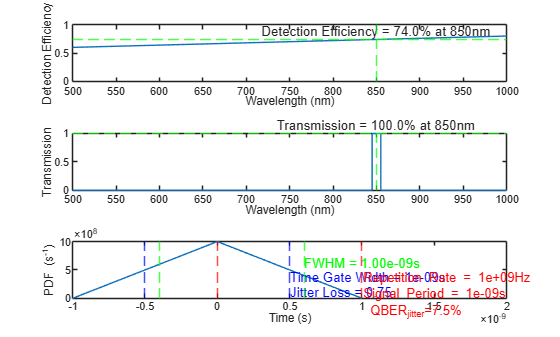

%2.1 Satellite
%2.1.1 Detector
Detector=components.Detector(wavelength, ...
    repetition_rate, ...
    time_gate_width, ...
    spectral_filter_width, ...
    "Preset","MicroPhotonDevices", ...
    "afterpulse_probability",afterpulse_probability,...
    "Dark_Count_Rate",dcr, ...
    "Wavelength_Range",wavelength_range,...
    "Efficiencies",efficiencies,...
    "Dead_Time",dead_time, ...
    "Jitter_Histogram",jitter_histogram,...
    "Histogram_Bin_Width",histogram_bin_width);

%view detector to make sure result has got across
Detector.plot();

%2.1.2 Receiver telescope
Receiver_Telescope=components.Telescope(receiver_telescope_diameter,...
                                        "Pointing_Jitter",1E-6);           %do not need to specify wavelength as this will be set by satellite object

%2.1.3 Construct satellite
SimSatellite=nodes.Satellite(Receiver_Telescope,...
                        'Detector', Detector,...
                        'OrbitDataFileLocation',orbit_data_file_location);

%2.2 Ground station
%2.2.1 Source
Transmitter_Source=components.Source(wavelength,...
                                    'Repetition_Rate',repetition_rate,...
                                    'MPN_Signal',mean_photon_numbers(1), ...
                                    'MPN_Decoy', mean_photon_numbers(2),...
                                    'Probability_Signal',state_probabilities(1),...
                                    'Probability_Decoy',state_probabilities(2));            
%2.2.2 Transmitter telescope
Transmitter_Telescope=components.Telescope(transmitter_telescope_diameter,...
                                           "Pointing_Jitter",1E-6);

%2.2.3 construct ground station, use Heriot-Watt as an example
SimGround_Station=nodes.GroundStation(Transmitter_Telescope,...
                                'Source',Transmitter_Source,...
                                'Detector',Detector,...
                                'LLA',[55.909723, -3.319995,10],...
                                'Name','HOGS');

## 3 Compose and run the PassSimulation

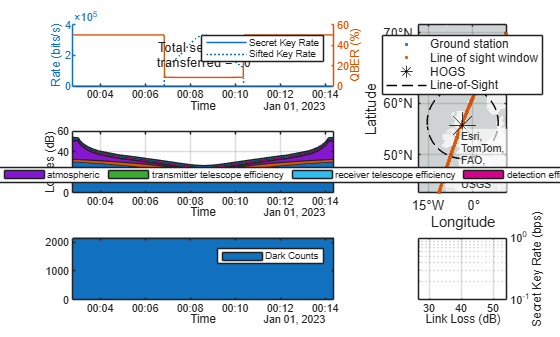

%3.1 run simulation, first argument is receiver
result = nodes.qkdPassSimulation(SimSatellite, SimGround_Station, protocol.DecoyBB84);
%3.2 plot results

result.plot('x_axis','Time','mask','Line of sight');